# Convection and conservation of mass equations

## Initial conditions

% Speed function u(t, x)
% a = -.02; b = -.05;
a = 2; b = 1;

u = @(t, x) a*x + b;
dudt = @(t, x) zeros(size(x));
dudx = @(t, x) a*ones(size(x));

% u = @(t, x) -a*x/200 + .5*t.*x;
% dudt = @(t, x) .5*x;
% dudx = @(t, x) -a/200 + .5*t;

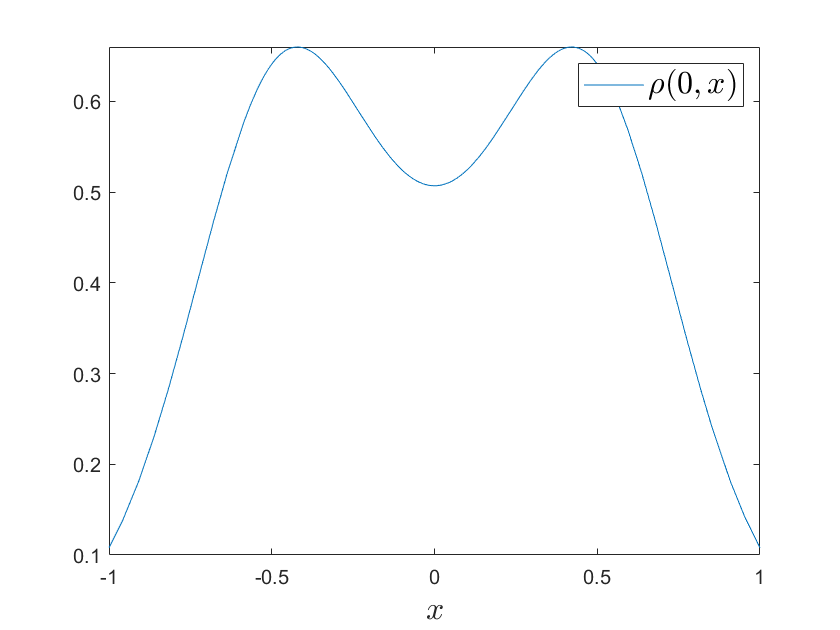

% Integration time
T = 1;
t = linspace(0, T, 11);

% Segment of interest
x = linspace(-1, 1, 51);

% Initial density distribution
rho_fun = @(x) .5*normpdf(x, 0, .5) + ...
    .25*normpdf(x, -.5, .25) + ...
    .25*normpdf(x, .5, .25);
rho_0 = rho_fun(x);


figure(1);
fplot(rho_fun, [min(x), max(x)]);
xlabel('$x$', Interpreter = 'latex', FontSize = 16);
legend('$\rho(0, x)$', Interpreter = 'latex', FontSize = 16);

## Characteristics

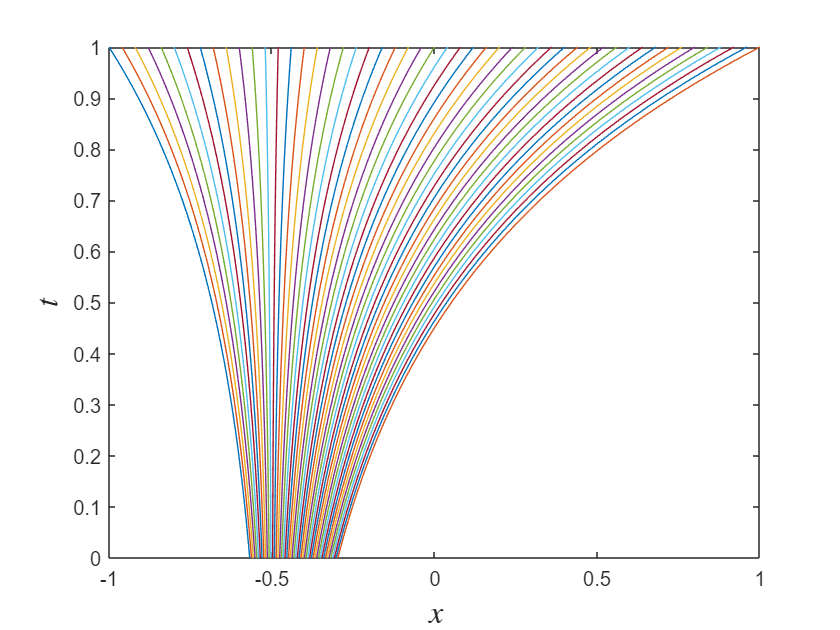

x0 = zeros(size(x));

figure(2)
for k = 1 : length(x)
    [t_path, x_path] = ode45(u, [T 0], x(k));
    plot(x_path, t_path);
    hold on;
    x0(k) = x_path(end);

    % Verification
%     x_path = x0(k) * exp(a*t) + b/a*(exp(a*t) - 1);
%     plot(x_path, t, '*k');
end
hold off;
xlabel('$x$', Interpreter = 'latex', FontSize = 16);
ylabel('$t$', Interpreter = 'latex', FontSize = 16);

## Interpolation of the density function at zeroth time

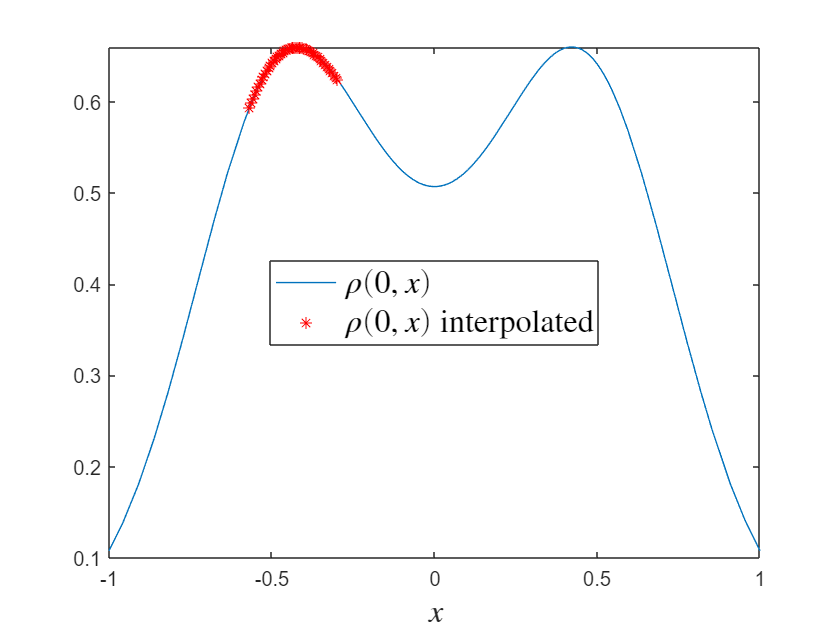

% Cubic interpolation
rho_0_app = spline(x, rho_0, x0);

figure(3)
fplot(rho_fun, [min([x, x0]), max([x, x0])]);
hold on;
plot(x0, rho_0_app, '*r');
hold off;
xlabel('$x$', Interpreter = 'latex', FontSize = 16);
legend('$\rho(0, x)$', '$\rho(0, x)$ interpolated', Interpreter = 'latex', FontSize = 16, Location = 'best');

## Conservation of mass equation

% figure(2)
rho = zeros(1, length(x));

for k = 1 : length(x)
    [t_path, x_path] = ode45(u, [T 0], x(k));
    app_rho_0 = spline(x, rho_0, x_path(end));

    dudx_path = dudx(t_path, x_path);
    dpath = [diff(x_path), diff(t_path)];
    h = sqrt(sum(dpath.^2, 2));

    integ = .5*(dudx_path(2:end) + dudx_path(1:end-1)).' * h;
    rho(k) = app_rho_0 * exp(-integ);
end

## Density change visualisation

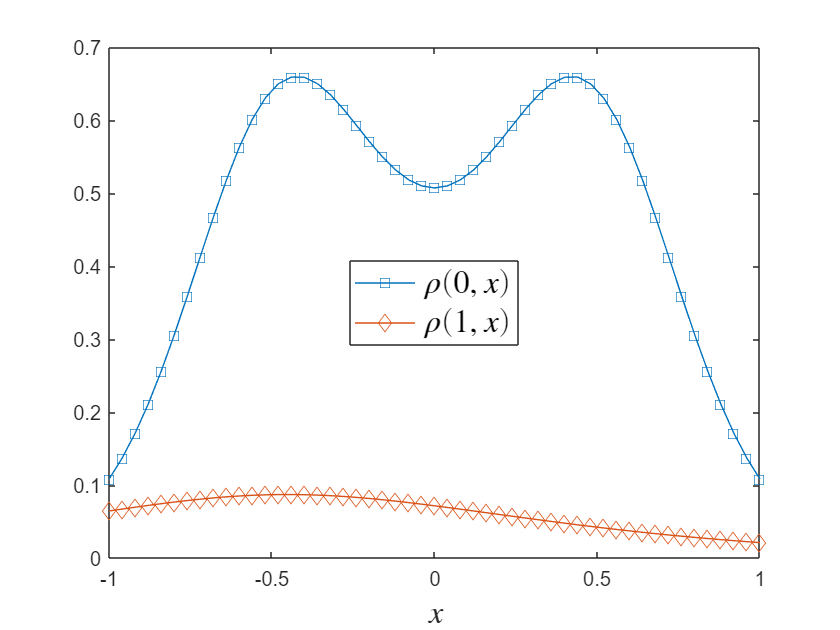

figure(3)
plot(x, rho_0, '-s');
hold on;
plot(x, rho, '-d');
hold off;
legend('$\rho(0, x)$', '$\rho(1, x)$', ...
    Interpreter = 'latex', FontSize = 16, Location = 'best');
xlabel('$x$', Interpreter = 'latex', FontSize = 16)